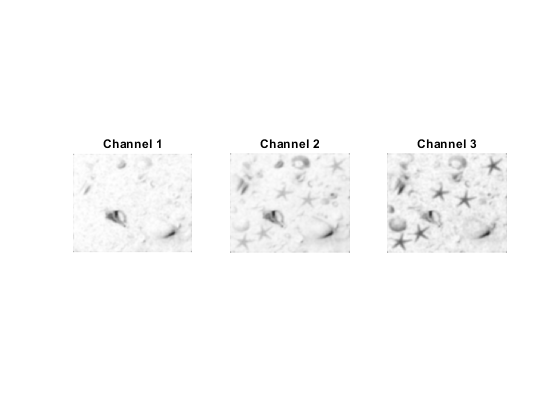

% Read images
original = imread('images\starfish.jpg');
im = original; % For processing

% Separate and denoise channels
[ch1,ch2,ch3] = imsplit(im);

figure
ch1 = medfilt2(ch1, [5 5]);
ch1 = imgaussfilt(ch1, 3);
subplot(1,3,1);
imshow(ch1)
title("Channel 1");

ch2 = medfilt2(ch2, [5 5]);
ch2 = imgaussfilt(ch2, 3);
subplot(1,3,2);
imshow(ch2)
title("Channel 2");

ch3 = medfilt2(ch3, [5 5]);
ch3 = imgaussfilt(ch3, 3);
subplot(1,3,3);
imshow(ch3)
title("Channel 3");

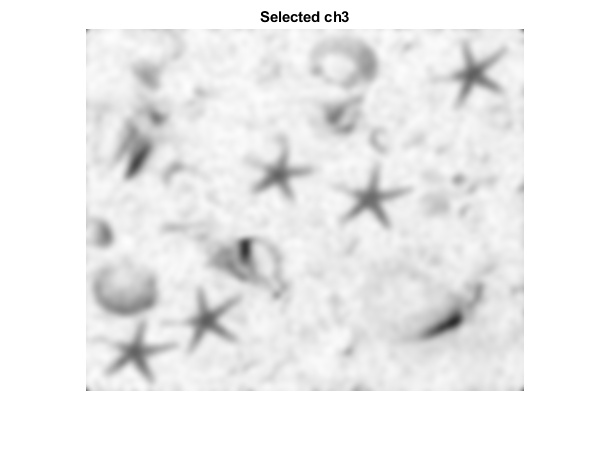


% Select channel with smallest range
ch1R = range(imhist(ch1));
ch2R = range(imhist(ch2));
ch3R = range(imhist(ch3));

selected = "none";
if ch1R < ch2R && ch1R < ch3R
    im = ch1;
    selected = "ch1";
elseif ch2R < ch1R && ch2R < ch3R
    im = ch2;
    selected = "ch2";
elseif ch3R < ch1R && ch3R < ch2R
    im = ch3;
    selected = "ch3";
end

figure
imshow(im)
title("Selected " + selected);

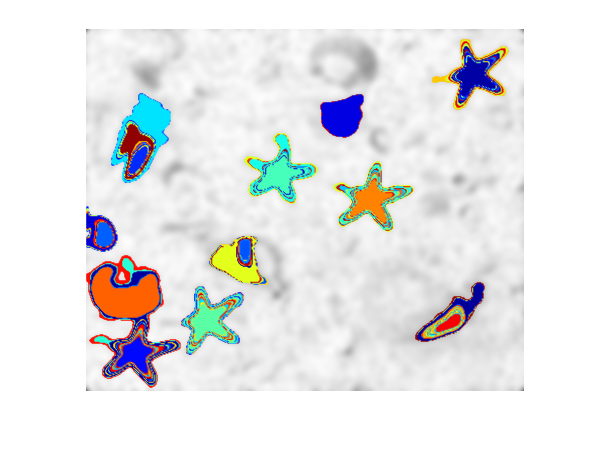


[regions,mserCC] = detectMSERFeatures(im);
figure;
imshow(im);
hold on;
plot(regions,'showPixelList',true,'showEllipses',false);


stats = regionprops('table',mserCC,'all');
prop = stats.Eccentricity < 0.5;
regions = regions(prop);
prop = stats. < 0.4;
regions = regions(prop);

The logical indices in position 1 contain a true value outside of the array bounds.


imshow(im);
hold on;
plot(regions,'showPixelList',true,'showEllipses',false);

% 
% % Bin
% im = ch3;
% im =
% DrawRois(original, im, 'r', 1, 'n');

function output = Process(inputIm)
    im = inputIm;
    
    % Make greyscale     
    im = rgb2gray(im);
    
    % Denoise
    im = imgaussfilt(im, 2);
    im = medfilt2(im, [5 5]);
    % Morphological ops
    se = strel('disk',5);
    im = imdilate(im, se);
    
    % Denoise
    im = imgaussfilt(im, 3);
    im = medfilt2(im, [7 7]);
    
    % Balance contrast
    im = histeq(im);
    
    % ...
    im = imfill(im, 'holes');
    
    % Make features smaller
    se = strel('disk',2);
    im = imerode(im, se);
    
    % Create segmentation mask.
    im = imbinarize(im, 0.9);
    
    % Remove extreme parts of mask.
    im = bwareafilt(im,[400 500]);
    % Enlarge the lesion.
    se = strel('disk',10);
    im = imdilate(im, se);
    
    % Return the processed image.
    output = im;
end
function stats = OverlayRois(imP, c, t, circle)
    CC = bwconncomp(imP); % get "connected components" in the binary mask
    % Uncomment to colour each segment randomly
    % L = labelmatrix(CC);
    % RGB = label2rgb(L,'cool','k','shuffle');
    % imshow(RGB)
    
    % Collate ALL region properties of each connect component (region) 
    stats = regionprops("table",CC,"all");
    
    % DRAW BOUNDING BOXES AND GET BLOB COUNT
    disp(CC.NumObjects + " objects detected") % Output text
    info = regionprops(CC,'Boundingbox') ; % Get region info from region properties
    
    % Draw bounding boxes for each region/connected component detected
    for k = 1 : length(info)
         BB = info(k).BoundingBox; % get bounding box measures for region 'k'
         if circle == 'n'
             rectangle('Position', [BB(1),BB(2),BB(3),BB(4)],'EdgeColor',c,'LineWidth',t); % Draw roi as rectangle with colour c and line thickness t.
         else
             rectangle('Position', [BB(1),BB(2),BB(3),BB(4)],'EdgeColor',c,'LineWidth',t,"Curvature",[1,1]) ; % Draw roi as circle "
         end
   end
end
% Simple facade for drawing rois on original image. c = colour of region
% outline, t = thickness, circle = 'y' or 'n' for circle or rect rois.
function stats = DrawRois(original, processed, c, t,circle)
    figure
    imshow(original)
    stats = OverlayRois(processed, c, t, circle);
end

